**Questão 10) **Um tubo de aço (k = 35 kcal/h-m.ºC e emissividade 0.55) cujo diâmetro externo é 5.1 cm e 2.2 m de comprimento conduz um fluido a 600 ºC, em um ambiente onde o ar está a 35 ºC (h = 20 kcal/h-m².ºC). Existem duas opções: elevar a transferência de calor, ou seja, o tubo pode receber 10 aletas de aço de 5 mm de espessura e 10.2 cm de diâmetro (aletas circulares) ou ser pintado com uma tinta de emissividade de 0.83. Determine:

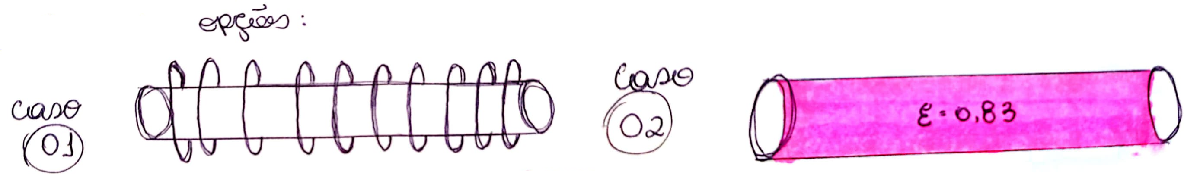

a) O fluxo de calor por convecção pelo tubo com aletas; 

Dados:


$$ℇ_{\mathrm{tubo}\;} =0,55$$
                                     

$\begin{array}{l}
L=2,2m\\
d_{\mathrm{ext}} =5,1\;\mathrm{cm}\\
h=20\;\frac{\mathrm{kcal}}{h-\mathrm{m²°}\cdot C}\\
T_s =600\;\mathrm{°C}\\
T_{\infty } =35\mathrm{°C}\\
K=35\;\frac{\mathrm{kcal}}{h-m\cdot \mathrm{°C}}\\
\sigma =4,88\cdot {10}^{-8} \frac{\mathrm{kcal}}{h\cdot \mathrm{m²}\cdot K^{4\;} }
\end{array}$Duas opções:            $\begin{array}{l}
e=5\mathrm{mm}\\
d_{\mathrm{aleta}} =10,2\mathrm{cm}\\
10\;\mathrm{aletas}
\end{array}$     ou      $\begin{array}{l}
\mathrm{Pintar}\;o\;\mathrm{tubo}\;\mathrm{com}\;\mathrm{uma}\;\mathrm{pintura}\;\mathrm{especial}\\
\mathrm{de}\;\mathrm{emissividade}\;0,83
\end{array}$

clear; clc; clearvars;
%Dados
e_tubo=0.55;
L=2.2; %m
d_e= 5.1; %cm
h= 20; %kcal/h-m².°C
Ts= 600; %°C
T_amb= 35; %°C
K= 35; %kcal/h-m°C
esp= 5; %mm
N= 10; %número de aletas
C= 4.88e-8; %constante Stefan-Boltzmann (kcal/h.m².K^4) 
d_a= 10.2; %cm
e_pint= 0.83;
% Tratamento de dados:
esp_m= 5/1000;
r_ext= (d_e/100)/2; %m
r_alet= (d_a/100)/2; %m
disp(['O raio externo é : ',num2str(r_ext),'m'])

O raio externo é : 0.0255m


disp(['O raio da aleta é : ',num2str(r_alet),'m'])

O raio da aleta é : 0.051m


Ts_K= Ts + 273.15; %Ts em Kelvin
Tamb_K= T_amb + 273.15; %Tamb em Kelvin

Calculando o coeficiente da aleta:


$$\begin{array}{l}
m=\sqrt{\frac{2\cdot h}{k\cdot e}}\\
m\cdot l=m\cdot \left(r_{\mathrm{al}} -r_{\mathrm{ext}} \right)
\end{array}$$


m= sqrt((2*h)/(K*esp_m));
ml= m*(r_alet-r_ext);

Calculando a eficiência da aleta:


$$\begin{array}{l}
\eta =\frac{\mathrm{tangh}\left(m\cdot l\right)}{m\cdot l}\;\;\;\;\;\;\;\;\;\;\;\\
\mathrm{tangh}\left(m\cdot l\right)=\frac{e^{m\cdot l} -e^{-m\cdot l} }{e^{m\cdot l} +e^{-m\cdot l} }
\end{array}$$


tangh= (exp(1)^(ml)-exp(1)^(-ml))/(exp(1)^(ml)+exp(1)^(-ml));
n= tangh/ml;
n_p= n*100;
disp(['tangh(ml) : ',num2str(tangh)])

tangh(ml) : 0.36749


disp(['A eficiência da aleta é : ',num2str(n),'  ou  ',num2str(n_p),'%'])

A eficiência da aleta é : 0.95324  ou  95.3235%


Após encontrada a eficiência da aleta, é necessário ainda encontrar a área não aletada e a área das aletas para poder substituir na fórmula do fluxo de calor com aletas, que é:


$$\dot{q_{\mathrm{conv}} =h\cdot \left(A_r +\eta \cdot A_A \right)\Delta T}$$


As= 2*pi*r_ext*L;
Ar= As - N*2*pi*r_ext*esp_m;
Aa= N*(2*pi*(r_alet^2 - r_ext^2));
deltaT= Ts-T_amb; %°C
qconv_al= h*(Ar+ n*Aa)*deltaT;
disp(['Área sem aletas: ',num2str(As),'m²'])

Área sem aletas: 0.35249m²


disp(['Área não aletada: ',num2str(Ar),'m²'])

Área não aletada: 0.34448m²


disp(['Área das aletas: ',num2str(Aa),'m²'])

Área das aletas: 0.12257m²


disp(['O fluxo de calor por convecção (tubo aletado) é: ',num2str(qconv_al),'kcal/h'])

O fluxo de calor por convecção (tubo aletado) é: 5212.8366kcal/h


x=-esp:0.1:2*pi; % define pontos no eixo x
y=sin(x); % seno de x
plot(x,y)
title('Exemplo de grafico com plot(): seno(x)') %

b) O fluxo de calor por radiação pelo tubo aletado; 


$$\dot{q_{\mathrm{rad}} } =\sigma \cdot \left(A_r +A_A \right)\cdot \varepsilon \cdot \left(T_s^{4\;} -T_{\infty }^4 \right)$$


qrad_al= C*(Ar+Aa)*e_tubo*(Ts_K^4 -Tamb_K^4);
disp(['O fluxo de calor por radiação (tubo aletado) é: ',num2str(qrad_al),'kcal/h'])

O fluxo de calor por radiação (tubo aletado) é: 7173.0949kcal/h


c) O fluxo de calor por radiação pelo tubo pintado;


$$\dot{q_{\mathrm{rad}} } =\sigma \cdot \left(A_r +A_A \right)\cdot \varepsilon \cdot \left(T_s^{4\;} -T_{\infty }^4 \right)$$


qrad_pint= C*As*e_pint*(Ts_K^4 -Tamb_K^4);
disp(['O fluxo de calor por radiação (tubo pintado) é: ',num2str(qrad_pint),'kcal/h'])

O fluxo de calor por radiação (tubo pintado) é: 8169.6999kcal/h


d) Qual opção produz a maior dissipação de calor? 

Primeiro é necessário encontrar o valor para o fluxo de calor por convecção para o tubo pintado:


$$\dot{q_{\mathrm{conv}} } =h\cdot A_s \cdot \Delta T$$


qconv_pint= h*As*deltaT;
disp(['O fluxo de calor por convecção (tubo pintado) é: ',num2str(qconv_pint),'kcal/h'])

O fluxo de calor por convecção (tubo pintado) é: 3983.0997kcal/h


Agora, é preciso calcular o fluxo total para cada caso:


$$\dot{q_{\mathrm{alet}} } =\dot{q_{\mathrm{conv}} } +\dot{q_{\mathrm{rad}} }$$



$$\dot{q_{\mathrm{pint}} } =\dot{q_{\mathrm{conv}} } +\dot{q_{\mathrm{rad}} }$$


qt_alet= qconv_al + qrad_al;
qt_pint= qconv_pint + qrad_pint;
disp(['O fluxo total de calor na primeira opção (sistema aletado) é: ',num2str(qt_alet),'kcal/h'])

O fluxo total de calor na primeira opção (sistema aletado) é: 12385.9315kcal/h


disp(['O fluxo total de calor na segunda opção (tubo pintado) é: ',num2str(qt_pint),'kcal/h'])

O fluxo total de calor na segunda opção (tubo pintado) é: 12152.7995kcal/h


Comparando os valores acima, percebe-se que:

if qt_alet > qt_pint
    disp('A opção de acrescentar aletas tem uma maior transferência de calor!')
else qt_alet < qt_pint
    disp('A opção do tubo pintado com tinta especial tem uma maior transferência de calor!')
end

A opção de acrescentar aletas tem uma maior transferência de calor!


ans = 50